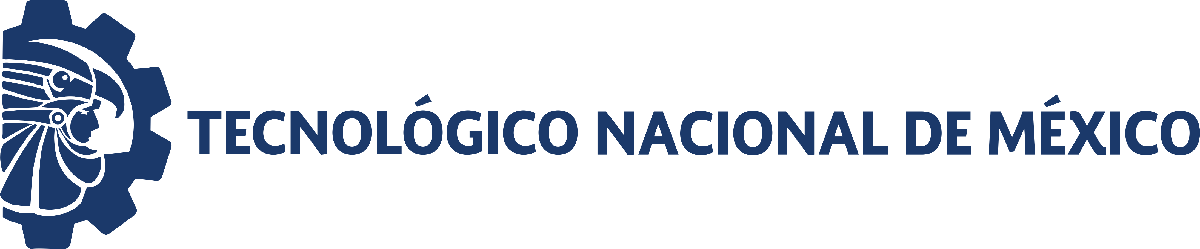                                 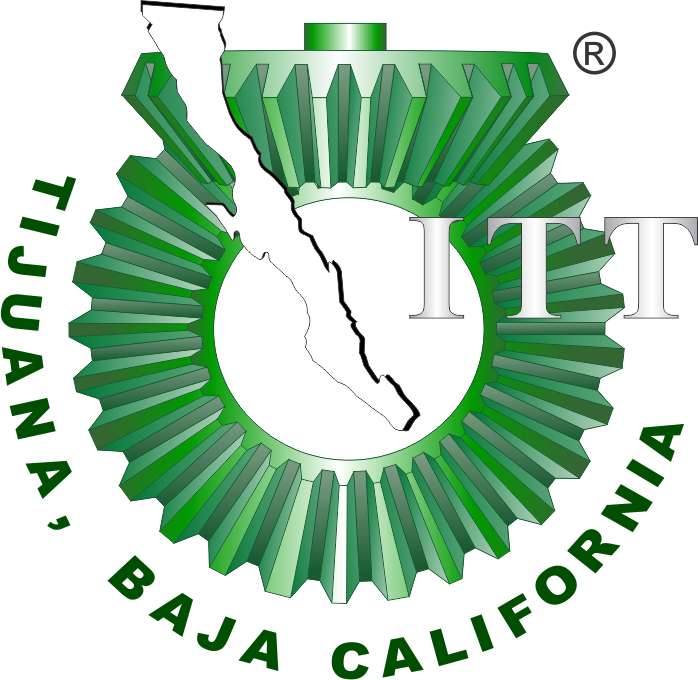

# Práctica 3: Liberación controlada de fármacos por hidrogeles

**Departamento de Ingeniería Eléctrica y Electrónica, Ingeniería Biomédica**

**Tecnológico Nacional de México [TecNM - Tijuana], Blvd. Alberto Limón Padilla s/n, C.P. 22454, Tijuana, B.C., México**

## Información general

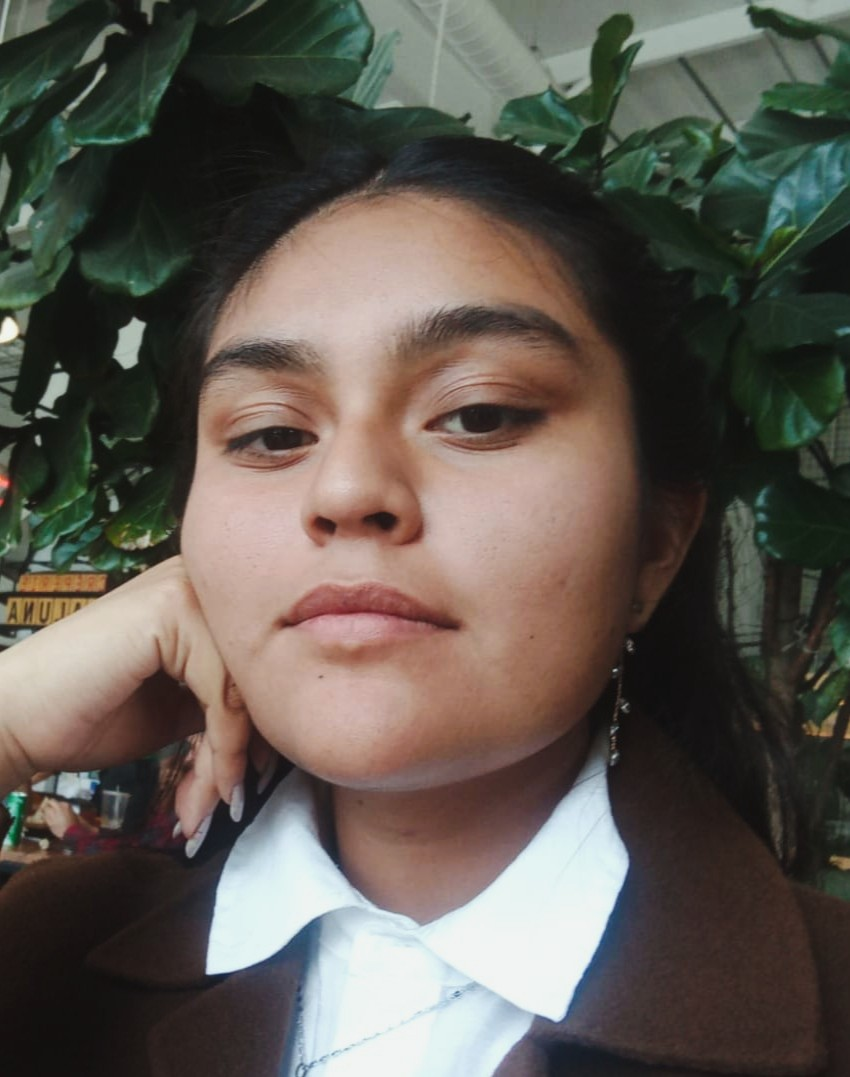

Nombre del alumno: **Bricia Idalia Arellano Salones**

Número de control: **22211746**

Correo institucional: **L22211746@tectijuana.edu.mx**

Asignatura: **Gemelos Digitales**

Docente: **Dr. Paul Antonio Valle Trujillo; paul.valle@tectijuana.edu.mx**

## Objetivo

Determinar la tasa de liberación del hidrogel N36 2MBA3 con base en los datos experimentales de la siguiente figura.

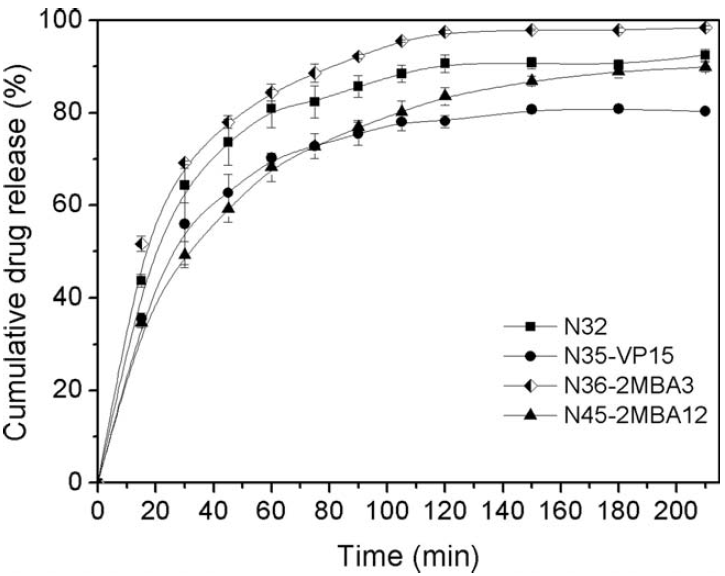

## Referencia

M. A. González‐Ayón, J.A. Sañudo‐Barajas, L.A. Picos‐Corrales, & A. Licea‐Claverie, "PNVCL‐PEGMA nanohydrogels with tailored transition temperature for controlled delivery of 5‐fluorouracil", *Journal of Polymer Science Part A: Polymer Chemistry*, vol. 53, issue 22, pp. 2662-2672, Aug 2015. DOI: [https://doi.org/10.1002/pola.27766](https://doi.org/10.1002/pola.27766)

## Modelos a ajustar a los datos experimentales

Ecuación de Peppas: $x\left(t\right)=kt^n$

Farmacocinética de primer orden: $$x(t) = \beta(1 - e^{-kt})$ $

Eureqa: $$x(t) = \rho_1 \sqrt t - \rho_2 t$ 
$

Eureqa: farmacocinética de primer orden: $$\dot x = \rho_1  - \rho_2 x$ 
$

## Datos experimentales

clc; clear; close all; warning('off','all')
% x1 = N45; x2 = N32; x3 = N35; x4 = N36;  
[t,x1,x2,x3,x4] = getdata('data.csv');
plotsys(t,x1,x2,x3,x4); sgtitle('Datos experimentales');...
exportgraphics(gcf, 'data_raw.pdf', 'ContentType', 'vector')

## Regresión no lineal, bioestadísticos y  experimentacion *in silico*

labels = {'x1(t): N45-2MBA12', 'x2(t): N32', 'x3(t): N35-VP15', 'x4(t): N36-2MBA3'};
x0 = [x1,x2,x3,x4]; s = size(x0);

### Función peppas

n0 = 0.1; k0 = 0.1; xp = zeros(s(1), s(2));
for i = 1:4
    disp(['Resultados para el Hidrogel:', string(labels(i))]);
    mdl = peppas(t,x0(:,i),[n0,k0]);
    xp(:,i) = mdl.Fitted; disp(' ');
end
plotresults(t,x0,xp); sgtitle('Peppas');...
exportgraphics(gcf, 'Peppas.pdf', 'ContentType', 'vector')

### Función farmacocinética de primer orden 

beta0 = 100; k0 = 0.01; xfc = zeros(s(1), s(2));
for i = 1:4
    disp(['Resultados para el Hidrogel:', string(labels(i))]);
    mdl = farmacocinetica(t,x0(:,i),[beta0,k0]);
    xfc(:,i) = mdl.Fitted; disp(' ');
end
plotresults(t,x0,xfc); sgtitle('Farmacocinética');...
exportgraphics(gcf, 'Farmacocinetica.pdf', 'ContentType', 'vector')

### Eureqa: Función en el tiempo 

    to       x1        x2        x3        x4  
    ___    ______    ______    ______    ______

      0         0         0         0         0
     15    34.783    43.739    35.478    51.391
     30    49.304    64.261    55.913     69.13
     45    59.304    73.565    62.609    77.826
     60    68.522     80.87    70.261    84.174
     75     72.87    82.348     72.87    88.522
     90     76.87    85.652    75.391    92.174
    105    80.348    88.435        78    95.391
    120    83.565    90.696    78.174    97.391
    150     86.87    90.957    80.783    97.739
    180    89.217    90.435     80.87    97.826
    210    90.087    92.522    80.435    98.435



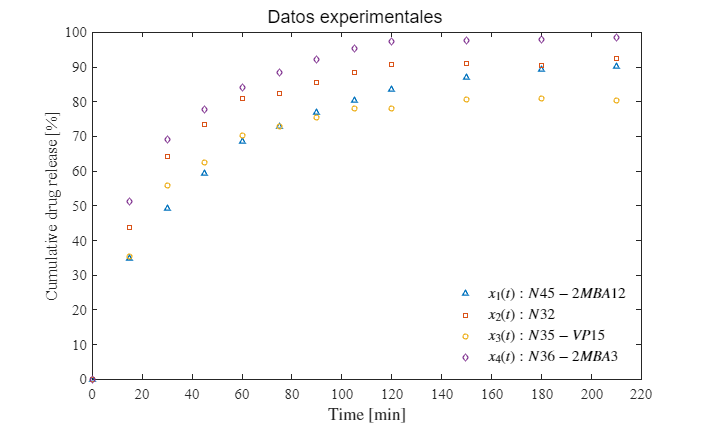

r1 = 15.7134422353809; r2 = 0.625638848781126;  xe = zeros(s(1), s(2));
for i = 1:4
    disp(['Resultados para el Hidrogel:', string(labels(i))]);
    mdl = eureqafunction(t,x0(:,i),[r1, r2]);
    xe(:,i) = mdl.Fitted; disp(' ');
end
plotresults(t,x0,xe); sgtitle('Eureqa');...

exportgraphics(gcf, 'Eureqa.pdf', 'ContentType', 'vector')

### Eureqa: Farmacocinética de primer orden

r1 = [2.29856104203723,3.186,2.671,3.501];  r2 = [0.0259881781667291, 0.03491, 0.03323,0.03545];  xed = zeros(s(1), s(2));
 Parameters = {'rho1'; 'rho2'};
for i = 1:4
    disp(['Resultados para el Hidrogel:', string(labels(i))]);
    [~,solV] = ode89(@(t,x) eureqaODE(x,[r1(i), r2(i)]), t, x0(1,i));
    xed(:,i) = solV; disp(' ');
       mdl = fitnlm(t, x0(:,i),  @(par, tq) modelODE(tq, x0(1,i), par),[r1(i), r2(i)]);    
        biostats(mdl, Parameters)
end
plotresults(t,x0,xed); sgtitle('Eureqa EDO');...

    "Resultados para el Hidrogel:"    "x1(t): N45-2MBA12"



Cantidad de datos: 12
Cantidad de parámetros: 2
Degrees of freedom: 10
t-student value: 2.2281
Significance value (alpha): 0.05
 
    Parameters    Estimate       SE         MoE             CI95             Pvalue  
    __________    ________    ________    ________    _________________    __________

      {'k'}        17.753       2.1439       4.777    12.976      22.53    8.6947e-06
      {'n'}       0.31603     0.025726    0.057321    0.2587    0.37335    2.3433e-07

R-cuadrada ordinaria: 0.98046
Suma residual de cuadrados: 154.2325
Criterio de información de Akaike ajustado (n/k <40): 70.0305

    "Resultados para el Hidrogel:"    "x2(t): N32"



Cantidad de datos: 12
Cantidad de parámetros: 2
Degrees of freedom: 10
t-student value: 2.2281
Significance value (alpha): 0.05
 
    Parameters    Estimate       SE         MoE              CI95             Pvalue  
    __________    ________    ________    ________    __________________    __________

      {'k'}        30.477        4.245      9.4584     21.018     39.935    2.9981e-05
      {'n'}          0.22     0.030141    0.067158    0.15285    0.28716    2.6037e-05

R-cuadrada ordinaria: 0.96384
Suma residual de cuadrados: 293.8584
Criterio de información de Akaike ajustado (n/k <40): 77.7662

    "Resultados para el Hidrogel:"    "x3(t): N35-VP15"



Cantidad de datos: 12
Cantidad de parámetros: 2
Degrees of freedom: 10
t-student value: 2.2281
Significance value (alpha): 0.05
 
    Parameters    Estimate       SE         MoE              CI95             Pvalue  
    __________    ________    ________    ________    __________________    __________

      {'k'}        24.724       3.8412      8.5587     16.165     33.283    7.4746e-05
      {'n'}       0.23632     0.033524    0.074696    0.16163    0.31102    3.5015e-05

R-cuadrada ordinaria: 0.95792
Suma residual de cuadrados: 271.7089
Criterio de información de Akaike ajustado (n/k <40): 76.8258

    "Resultados para el Hidrogel:"    "x4(t): N36-2MBA3"



Cantidad de datos: 12
Cantidad de parámetros: 2
Degrees of freedom: 10
t-student value: 2.2281
Significance value (alpha): 0.05
 
    Parameters    Estimate       SE         MoE              CI95             Pvalue  
    __________    ________    ________    ________    __________________    __________

      {'k'}          34.1       3.8322      8.5387     25.562     42.639    4.5824e-06
      {'n'}       0.21105     0.024357    0.054272    0.15678    0.26532    5.8147e-06

R-cuadrada ordinaria: 0.97533
Suma residual de cuadrados: 224.0764
Criterio de información de Akaike ajustado (n/k <40): 74.5128

exportgraphics(gcf, 'Eureqa_EDO.pdf', 'ContentType', 'vector')

## Funciones

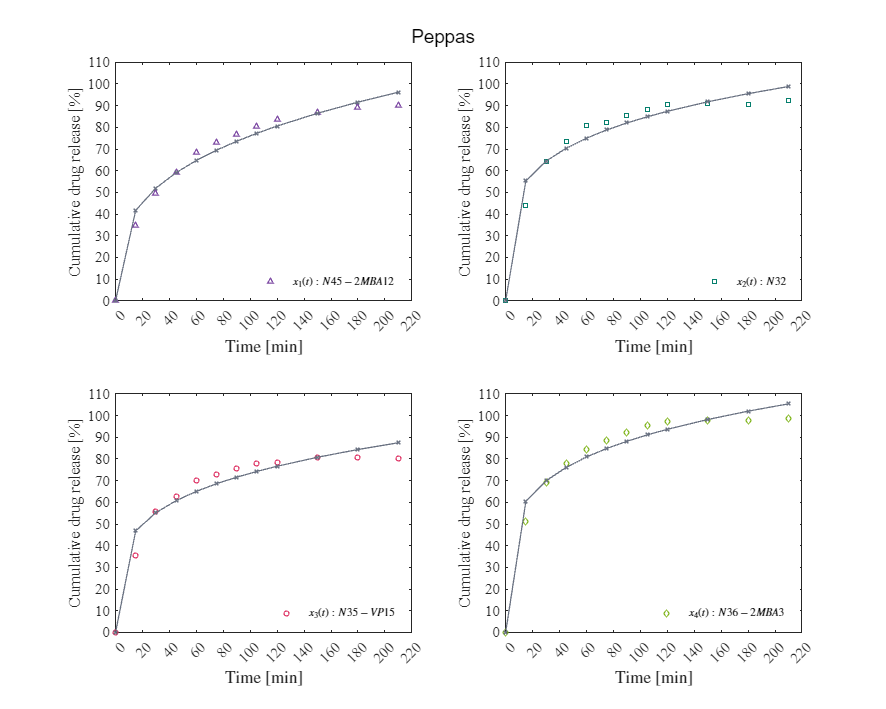

function plotsys(to,x1,x2,x3,x4)

    mycolors = [0.4980,    0.2980,    0.6471;
                0.0196,    0.4980,    0.4275;
                0.8745,    0.2235,    0.4118;
                % 0.4824,    0.1765,    0.2627;
                0.4863,    0.7020,    0.0824;
                % 0.1333,    0.1098,    0.3686;
                % 0.8118,    0.6745,    0.0824;

    "Resultados para el Hidrogel:"    "x1(t): N45-2MBA12"



Cantidad de datos: 12
Cantidad de parámetros: 2
Degrees of freedom: 10
t-student value: 2.2281
Significance value (alpha): 0.05
 
    Parameters    Estimate       SE          MoE               CI95              Pvalue  
    __________    ________    _________    ________    ____________________    __________

     {'beta'}       87.884       1.5019      3.3465      84.538      91.231    5.1597e-14
     {'k'   }     0.026047    0.0015726    0.003504    0.022543    0.029551    1.3439e-08

R-cuadrada ordinaria: 0.99057
Suma residual de cuadrados: 74.4616
Criterio de información de Akaike ajustado (n/k <40): 61.2924

    "Resultados para el Hidrogel:"    "x2(t): N32"



Cantidad de datos: 12
Cantidad de parámetros: 2
Degrees of freedom: 10
t-student value: 2.2281
Significance value (alpha): 0.05
 
    Parameters    Estimate       SE           MoE               CI95              Pvalue  
    __________    ________    _________    _________    ____________________    __________

     {'beta'}       89.993      0.83795       1.8671      88.126       91.86    1.2009e-16
     {'k'   }     0.040311    0.0017625    0.0039271    0.036384    0.044238    5.7611e-10

R-cuadrada ordinaria: 0.99524
Suma residual de cuadrados: 38.7062
Criterio de información de Akaike ajustado (n/k <40): 53.441

    "Resultados para el Hidrogel:"    "x3(t): N35-VP15"



Cantidad de datos: 12
Cantidad de parámetros: 2
Degrees of freedom: 10
t-student value: 2.2281
Significance value (alpha): 0.05
 
    Parameters    Estimate       SE           MoE               CI95              Pvalue  
    __________    ________    _________    _________    ____________________    __________

     {'beta'}       79.571      0.67237       1.4981      78.073      81.069    4.5519e-17
     {'k'   }     0.037275    0.0014063    0.0031335    0.034141    0.040408    1.3478e-10

R-cuadrada ordinaria: 0.99642
Suma residual de cuadrados: 23.1348
Criterio de información de Akaike ajustado (n/k <40): 47.265

    "Resultados para el Hidrogel:"    "x4(t): N36-2MBA3"



Cantidad de datos: 12
Cantidad de parámetros: 2
Degrees of freedom: 10
t-student value: 2.2281
Significance value (alpha): 0.05
 
    Parameters    Estimate       SE           MoE               CI95              Pvalue  
    __________    ________    _________    _________    ____________________    __________

     {'beta'}       96.091       1.3541        3.017      93.074      99.108    7.5283e-15
     {'k'   }     0.041833    0.0028345    0.0063157    0.035517    0.048149    4.0867e-08

R-cuadrada ordinaria: 0.9885
Suma residual de cuadrados: 104.4403
Criterio de información de Akaike ajustado (n/k <40): 65.3524

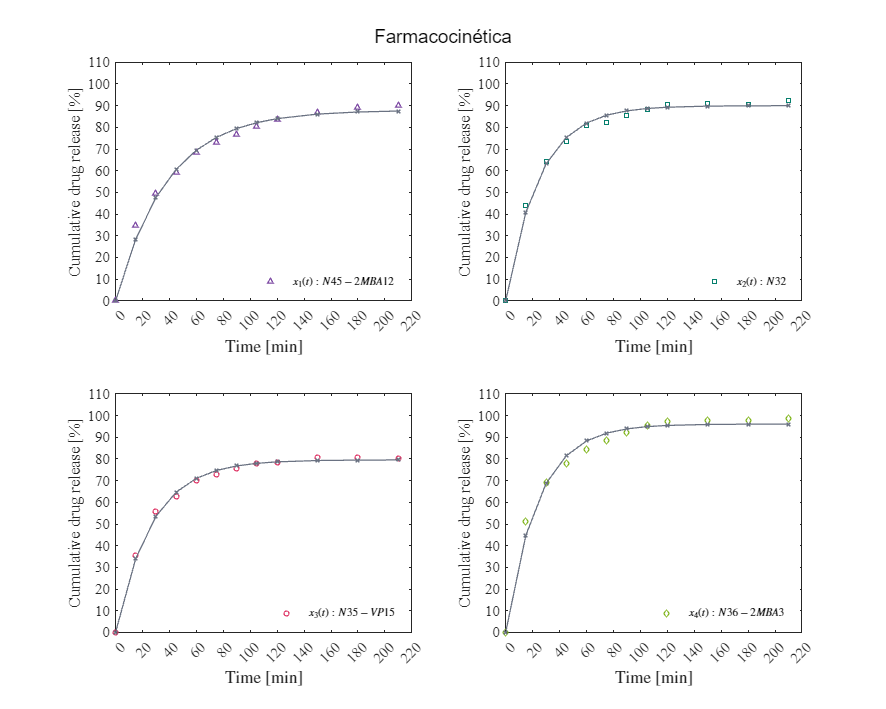

                0.5373,    0.5765,    0.9804];
colororder(mycolors);

set( figure(), 'Color', 'w')
FS = 12; 
set(gcf, 'Units', 'Centimeters', 'Position', [1,1,20,12])
r = table(to,x1,x2,x3,x4); disp(r);
hold on; box on; grid off;
plot(to,x1,'^',to,x2,'s',to,x3,'o',to,x4,'d','LineWidth',1, 'MarkerSize', 4)
L = legend('$x_1(t): N45-2MBA12$', '$x_2(t): N32$', '$x_3(t): N35-VP15$', '$x_4(t): N36-2MBA3$');
set(L, 'Interpreter', 'Latex', 'FontSize', FS, 'Location', 'SouthEast', 'Box', 'Off');

    "Resultados para el Hidrogel:"    "x1(t): N45-2MBA12"



Cantidad de datos: 12
Cantidad de parámetros: 2
Degrees of freedom: 10
t-student value: 2.2281
Significance value (alpha): 0.05
 
    Parameters    Estimate       SE         MoE              CI95             Pvalue  
    __________    ________    ________    ________    __________________    __________

     {'rho1'}      11.212      0.22178     0.49415     10.718     11.706    2.2167e-13
     {'rho2'}     0.33749     0.019147    0.042661    0.29483    0.38015    7.3513e-09

R-cuadrada ordinaria: 0.99648
Suma residual de cuadrados: 27.7864
Criterio de información de Akaike ajustado (n/k <40): 49.4635

    "Resultados para el Hidrogel:"    "x2(t): N32"



Cantidad de datos: 12
Cantidad de parámetros: 2
Degrees of freedom: 10
t-student value: 2.2281
Significance value (alpha): 0.05
 
    Parameters    Estimate       SE         MoE             CI95             Pvalue  
    __________    ________    ________    ________    _________________    __________

     {'rho1'}      14.547        0.261     0.58154    13.965     15.128    8.3842e-14
     {'rho2'}      0.5728     0.022533    0.050207    0.5226    0.62301    2.0354e-10

R-cuadrada ordinaria: 0.99526
Suma residual de cuadrados: 38.4842
Criterio de información de Akaike ajustado (n/k <40): 53.372

    "Resultados para el Hidrogel:"    "x3(t): N35-VP15"



Cantidad de datos: 12
Cantidad de parámetros: 2
Degrees of freedom: 10
t-student value: 2.2281
Significance value (alpha): 0.05
 
    Parameters    Estimate       SE         MoE             CI95             Pvalue  
    __________    ________    ________    ________    _________________    __________

     {'rho1'}      12.483      0.27749     0.61829    11.865     13.101    7.0894e-13
     {'rho2'}     0.47888     0.023957    0.053379    0.4255    0.53226    2.1572e-09

R-cuadrada ordinaria: 0.99326
Suma residual de cuadrados: 43.5013
Criterio de información de Akaike ajustado (n/k <40): 54.8425

    "Resultados para el Hidrogel:"    "x4(t): N36-2MBA3"



Cantidad de datos: 12
Cantidad de parámetros: 2
Degrees of freedom: 10
t-student value: 2.2281
Significance value (alpha): 0.05
 
    Parameters    Estimate       SE         MoE              CI95             Pvalue  
    __________    ________    ________    ________    __________________    __________

     {'rho1'}      15.694      0.12883     0.28706     15.407     15.981    3.4089e-17
     {'rho2'}     0.62215     0.011123    0.024782    0.59737    0.64693    8.0878e-14

R-cuadrada ordinaria: 0.99897
Suma residual de cuadrados: 9.3767
Criterio de información de Akaike ajustado (n/k <40): 36.4278

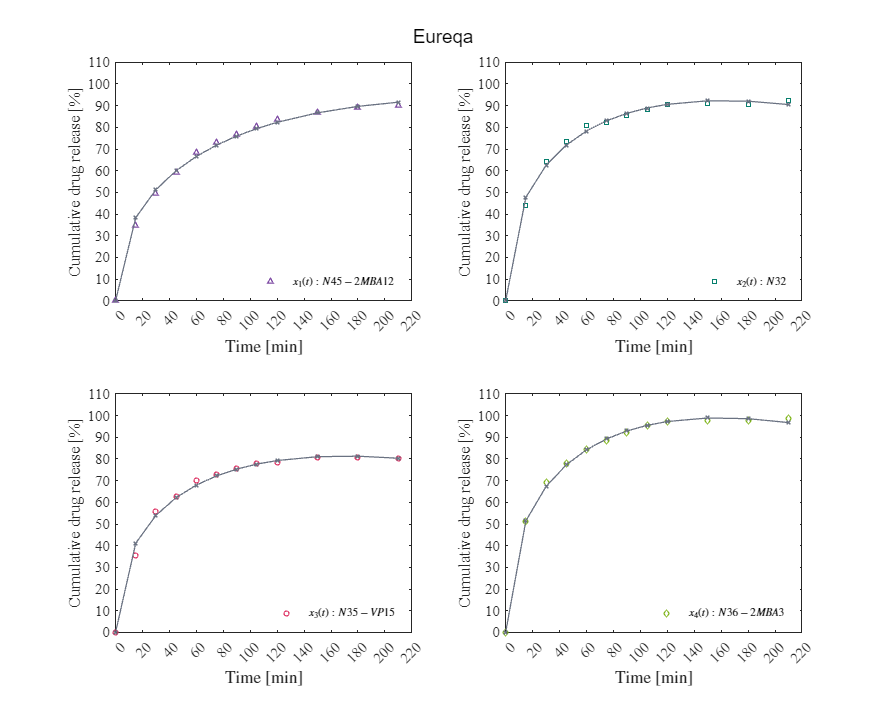

xlabel ('Time [min]', 'Interpreter', 'latex', 'FontSize', FS)
ylabel ('Cumulative drug release [%]', 'Interpreter', 'latex', 'FontSize', FS)

set (gca, 'FontName', 'Times New Roman', 'FontSize', FS);
xlim([0 220]); xticks(0:20:220);
ylim([0 100]); yticks(0:10:100);
end

function plotresults(t,xa,xb)
    mycolors = [0.4980,    0.2980,    0.6471;
                0.0196,    0.4980,    0.4275;
                0.8745,    0.2235,    0.4118;
                0.2000,    0.7804,    0.8471;

    "Resultados para el Hidrogel:"    "x1(t): N45-2MBA12"



Cantidad de datos: 12
Cantidad de parámetros: 2
Degrees of freedom: 10
t-student value: 2.2281
Significance value (alpha): 0.05
 
    Parameters    Estimate       SE          MoE               CI95              Pvalue  
    __________    ________    _________    ________    ____________________    __________

     {'rho1'}       2.2891      0.11148      0.2484      2.0407      2.5375     1.659e-09
     {'rho2'}     0.026047    0.0015726    0.003504    0.022543    0.029551    1.3442e-08

R-cuadrada ordinaria: 0.99057
Suma residual de cuadrados: 74.4616
Criterio de información de Akaike ajustado (n/k <40): 61.2924

    "Resultados para el Hidrogel:"    "x2(t): N32"



Cantidad de datos: 12
Cantidad de parámetros: 2
Degrees of freedom: 10
t-student value: 2.2281
Significance value (alpha): 0.05
 
    Parameters    Estimate       SE           MoE               CI95              Pvalue  
    __________    ________    _________    _________    ____________________    __________

     {'rho1'}       3.6277      0.14004      0.31203      3.3156      3.9397      1.69e-10
     {'rho2'}     0.040311    0.0017625    0.0039271    0.036384    0.044238    5.7613e-10

R-cuadrada ordinaria: 0.99524
Suma residual de cuadrados: 38.7062
Criterio de información de Akaike ajustado (n/k <40): 53.441

    "Resultados para el Hidrogel:"    "x3(t): N35-VP15"



Cantidad de datos: 12
Cantidad de parámetros: 2
Degrees of freedom: 10
t-student value: 2.2281
Significance value (alpha): 0.05
 
    Parameters    Estimate       SE           MoE               CI95              Pvalue  
    __________    ________    _________    _________    ____________________    __________

     {'rho1'}        2.966     0.097527       0.2173      2.7487      3.1833    3.4613e-11
     {'rho2'}     0.037275    0.0014063    0.0031335    0.034141    0.040408    1.3479e-10

R-cuadrada ordinaria: 0.99642
Suma residual de cuadrados: 23.1348
Criterio de información de Akaike ajustado (n/k <40): 47.265

    "Resultados para el Hidrogel:"    "x4(t): N36-2MBA3"



Cantidad de datos: 12
Cantidad de parámetros: 2
Degrees of freedom: 10
t-student value: 2.2281
Significance value (alpha): 0.05
 
    Parameters    Estimate       SE           MoE               CI95              Pvalue  
    __________    ________    _________    _________    ____________________    __________

     {'rho1'}       4.0198      0.24186      0.53889      3.4809      4.5586    1.2998e-08
     {'rho2'}     0.041833    0.0028345    0.0063158    0.035517    0.048149    4.0868e-08

R-cuadrada ordinaria: 0.9885
Suma residual de cuadrados: 104.4403
Criterio de información de Akaike ajustado (n/k <40): 65.3524

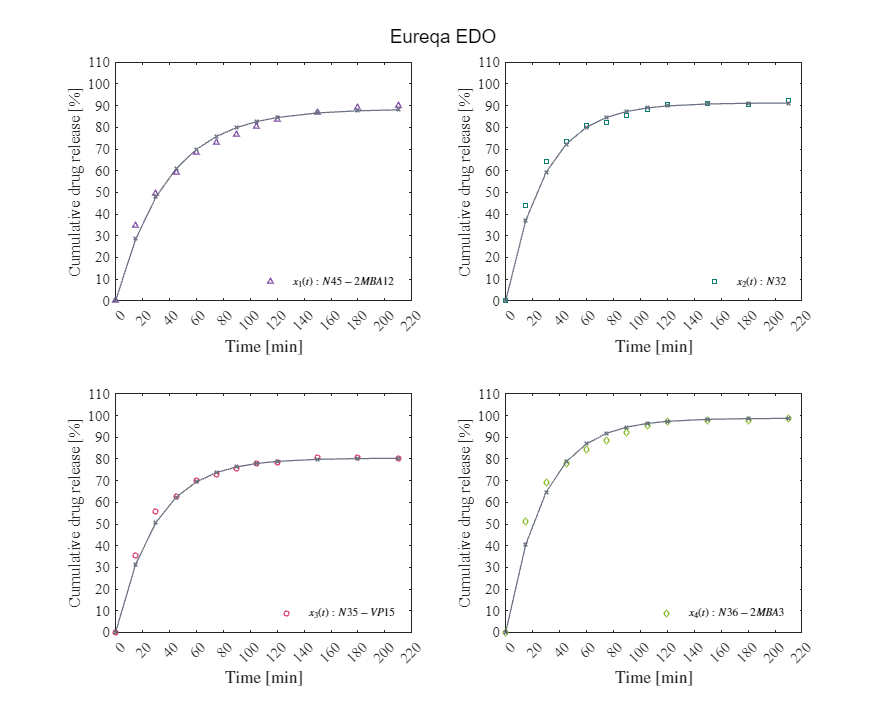

                1.0000,    0.5529,    0.0784;
                0.4824,    0.1765,    0.2627;

                0.4863,    0.7020,    0.0824;
                0.1333,    0.1098,    0.3686;
                0.8118,    0.6745,    0.0824;
                0.5373,    0.5765,    0.9804;
                0.4157      0.4471    0.5098];
set( figure(), 'Color', 'w')
FS = 12; 
set(gcf, 'Units', 'Centimeters', 'Position', [1,1,25,20])
subplot (2,2,1)
hold on; box on; grid off;
plot(t,xa(:,1),'^', 'LineWidth',1, 'MarkerSize', 4, 'Color', mycolors(1, :))
plot(t,xb(:,1), '-x', 'LineWidth',1, 'MarkerSize', 4, 'Color', mycolors(11, :))
xlabel ('Time [min]', 'Interpreter', 'latex', 'FontSize', FS)
ylabel ('Cumulative drug release [%]', 'Interpreter', 'latex', 'FontSize', FS)
L = legend('$x_1(t): N45-2MBA12$' );
set(L, 'Interpreter', 'Latex', 'FontSize', 9, 'Box','Off', 'Location', 'SouthEast');
set (gca, 'FontName', 'Times New Roman', 'FontSize', FS);
xlim([0 220]); xticks(0:20:220);
ylim([0 110]); yticks(0:10:110);
subplot (2,2,2)
hold on; box on; grid off; 
plot(t,xa(:,2),'s', 'LineWidth',1, 'MarkerSize', 4, 'Color', mycolors(2, :))
plot(t,xb(:,2), '-x', 'LineWidth',1, 'MarkerSize', 4, 'Color', mycolors(11, :))
xlabel ('Time [min]', 'Interpreter', 'latex', 'FontSize', FS)
ylabel ('Cumulative drug release [%]', 'Interpreter', 'latex', 'FontSize', FS)
L = legend('$x_2(t): N32$' );
set(L, 'Interpreter', 'Latex', 'FontSize', 9, 'Box','Off', 'Location', 'SouthEast');
set (gca, 'FontName', 'Times New Roman', 'FontSize', FS);
xlim([0 220]); xticks(0:20:220);
ylim([0 110]); yticks(0:10:110);
subplot (2,2,3)
hold on; box on; grid off; 
plot(t,xa(:,3),'o', 'LineWidth',1, 'MarkerSize', 4, 'Color', mycolors(3, :))
plot(t,xb(:,3), '-x', 'LineWidth',1, 'MarkerSize', 4, 'Color', mycolors(11, :))
xlabel ('Time [min]', 'Interpreter', 'latex', 'FontSize', FS)
ylabel ('Cumulative drug release [%]', 'Interpreter', 'latex', 'FontSize', FS)
L = legend('$x_3(t): N35-VP15$' );
set(L,  'Interpreter', 'Latex','FontSize', 9, 'Box','Off', 'Location', 'SouthEast');
set (gca, 'FontName', 'Times New Roman', 'FontSize', FS);
xlim([0 220]); xticks(0:20:220);
ylim([0 110]); yticks(0:10:110);
subplot (2,2,4)
hold on; box on; grid off; 
plot(t,xa(:,4),'d', 'LineWidth',1, 'MarkerSize', 4, 'Color', mycolors(7, :))
plot(t,xb(:,4), '-x', 'LineWidth',1, 'MarkerSize', 4, 'Color', mycolors(11, :))
xlabel ('Time [min]', 'Interpreter', 'latex', 'FontSize', FS)
ylabel ('Cumulative drug release [%]', 'Interpreter', 'latex', 'FontSize', FS)
L = legend('$x_4(t): N36-2MBA3$' );
set(L,  'Interpreter', 'Latex','FontSize', 9, 'Box','Off', 'Location', 'SouthEast');
set (gca, 'FontName', 'Times New Roman', 'FontSize', FS);
xlim([0 220]); xticks(0:20:220);
ylim([0 110]); yticks(0:10:110);
end

### Datos experimentales

function [to,x1,x2,x3,x4] = getdata(file)
    sys = readmatrix(file);
    to = round(sys(:,1));
    x1 = sys(:,2);
    x2 = sys(:,3);
    x3 = sys(:,4);
    x4 = sys(:,5);
end

### Modelos matemáticos y bioestadísticos


 function biostats (mdl, Parameters)
    Estimate = table2array(mdl.Coefficients(:,1));
    SE =table2array(mdl.Coefficients(:,2));
    Pvalue = table2array(mdl.Coefficients(:,4));
    alpha = 0.05; 
    CI95 = coefCI(mdl, alpha);
    dof = mdl.DFE;
    tval = tinv(1-alpha/2,dof);
    MoE = SE*tval;
    Results = table(Parameters, Estimate, SE,MoE,CI95,Pvalue);
    disp(['Cantidad de datos: ',num2str(mdl.NumObservations)])
    disp(['Cantidad de parámetros: ', num2str(mdl.NumVariables)])
    disp(['Degrees of freedom: ', num2str(dof)])
    disp(['t-student value: ',num2str(tval)])
    disp(['Significance value (alpha): ', num2str(alpha)])
    disp(' '); disp(Results);
    R2o = mdl.Rsquared.Ordinary;
    % R2a = mdl.Rsquared.Adjusted;
    SSE = mdl.SSE;
    % AIC = mdl.ModelCriterion.AIC;
    AICc = mdl.ModelCriterion.AICc; 
    fprintf(['R-cuadrada ordinaria: ', num2str(R2o)]);...
    fprintf(['\nSuma residual de cuadrados: ', num2str(SSE)]);...
    % fprintf(['\nCriterio de información de Akaike: ', num2str(AIC)]);...
    fprintf(['\nCriterio de información de Akaike ajustado (n/k <40): ', num2str(AICc)]);
    end


### Regresión: Función de Peppas

function mdl = peppas(to,xo,par)
Parameters = {'k'; 'n'};
    function x = model(par,t)
            k = par(1); n = par(2);
            x = k*t.^n;
    end
    mdl = fitnlm(to, xo, @model, par);
    biostats(mdl, Parameters)
end

### Función farmacocinética


function mdl = farmacocinetica(to,xo,par)
 Parameters = {'beta'; 'k'};
    function x = model(par,t)
            b = par(1); k = par(2); 
            x = b*(1-exp(-(k*t)));
            
    end
    mdl = fitnlm(to, xo, @model, par);
    biostats(mdl, Parameters)
end

### Eureqa: función en el tiempo

function mdl = eureqafunction(to,xo,par)
 Parameters = {'rho1'; 'rho2'};
    function x = model(par,t)
            r1 = par(1); r2 = par(2); 
            x = r1*sqrt(t) - r2*t;
    end
    mdl = fitnlm(to, xo, @model, par);
    biostats(mdl, Parameters)
end 

### Eureqa: farmacocinética de primer orden

function dxdt = eureqaODE(x,par)
            r1   = par(1); r2   = par(2);
            dxdt = r1 - r2*x;
end 
function xsim = modelODE(tq, x0_i, par)
    [~, sol] = ode89(@(t,x) eureqaODE(x, par), tq, x0_i);
    xsim = sol;
end